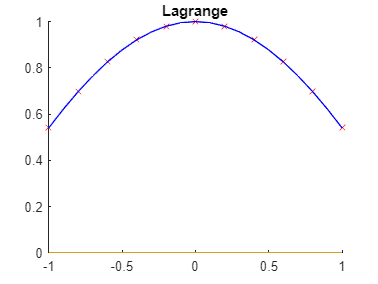

startX = -1;
stepX = 0.2;
endX = 1;

X = startX:stepX:endX;
Y = cos(X);


n = length(X);



step_size = 0.1;

x_values = startX:step_size:endX;


L = polyval(lagrange(X, Y),x_values);
N = polyval(newton(X, Y),x_values);
M = polyval(polyfit(X, Y, n-1),x_values);






figure;
hold on;
scatter(X, Y, 'xr');
plot(x_values, L, 'b');
plot(X, zeros(1, length(X)));
title('Lagrange');

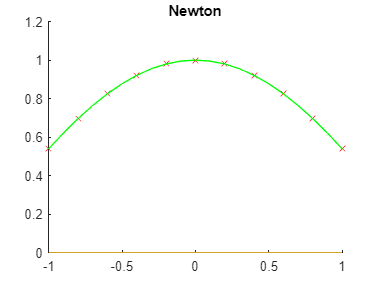


figure;
hold on;
scatter(X, Y, 'xr');
plot(x_values, N, 'g');
plot(X, zeros(1, length(X)));
title('Newton');

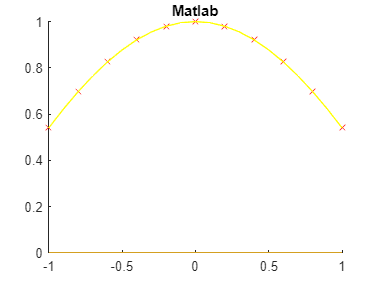


figure;
hold on;
scatter(X, Y, 'xr');
plot(x_values, M, 'y');
plot(X, zeros(1, length(X)));
title('Matlab');



for i = 1:n
    fprintf('L(%d) = %.5f, N(%d) = %.5f, M(%d) = %.5f\n', i, L(i), i, N(i), i, M(i));
end

L(1) = 0.54030, N(1) = 0.54030, M(1) = 0.54030
L(2) = 0.62161, N(2) = 0.62161, M(2) = 0.62161
L(3) = 0.69671, N(3) = 0.69671, M(3) = 0.69671
L(4) = 0.76484, N(4) = 0.76484, M(4) = 0.76484
L(5) = 0.82534, N(5) = 0.82534, M(5) = 0.82534
L(6) = 0.87758, N(6) = 0.87758, M(6) = 0.87758
L(7) = 0.92106, N(7) = 0.92106, M(7) = 0.92106
L(8) = 0.95534, N(8) = 0.95534, M(8) = 0.95534
L(9) = 0.98007, N(9) = 0.98007, M(9) = 0.98007
L(10) = 0.99500, N(10) = 0.99500, M(10) = 0.99500
L(11) = 1.00000, N(11) = 1.00000, M(11) = 1.00000
